# Reto - Innovación en el diseño de producto en la industria vidriera

Equipo 2:

Ana Fernanda Chacón A00830052

Ana Paula Ruiz A01367467

Juan Carlos Puig A01721029

Heberto Villalobos A01562407

TC1003B Modelación de la ingeniería con matemática computacional

Grupo 4 (Horario de 11:00 - 15:00)

El presente código permite visualizar el boceto de la propuesta de producto, la cual consiste en una taza de vidrio con un dispositivo en la base para que el envase caliente la bebida por sí solo. Primero se realiza la interpolación de las matrices formadas por los puntos seleccionados para graficar un boceto final tridimensional de nuestro prototipo de taza. Dicho proceso se hace a través de cinco interpolaciones: dos lineales y dos cuadráticas para la taza, y una cuadrática para la agarradera. De manera que al unir las gráficas, se forma el perfil de la taza y al rotarlo sobre su eje se termina con una simulación tridimensional del producto. Despúes se determina el volumen de la taza que será ocupado por vidrio para poder hacer una cotización del precio final del producto.

### Puntos elegidos

%Para la taza
x1 = 6.3;
x2 = 5.5;
x3 = 5.7;
x4 = 6;
x5 = 4;
x6 = 6;
x10 = 0;

y1 = 10;
y2 = 9;
y3 = 8;
y4 = 6;
y5 = 1;
y6 = 0;
y10 = 0;

%Para la agarradera
x7 = 5.8;
x8 = 8;
x9 = 5.5;

y7 = 7.5;
y8 = 6;
y9 = 3.5;

## Primera interpolación

2 puntos:

(6, 0)

(4, 1)

Por ende utilizamos un sistema de ecuaciones lineales:

0 = a1(6) + a0

1 = a1(4) + a0

A1 = [1,x6;1,x5]

A1 =      1     6
     1     4


B1 = [y6;y5]

B1 =      0
     1



X1=inv(A1)*B1

X1 =     3.0000
   -0.5000



fprintf("La ecuación es y = %fx + %f",X1(2),X1(1))

La ecuación es y = -0.500000x + 3.000000

## Segunda interpolación

3 puntos:

(4, 1)

(7, 6)

(5.7, 8)

Por ende utilizamos un sistema de ecuaciones de grado 2:

debido a que queremos que la gráfica sea una parábola acostada (su ecuación es de la forma x = a2*y^2 + a1*y + a0), el valor de "y" es el que estará dentro de la matriz de coeficientes A y el valor de "x" dentro de la matriz de resultados B

4 = a2(1)^2 + a1(1) + a0

7 = a2(6)^2 + a1(6) + a0

5.7 = a2(8)^2 + a1(8) + a0

A2 = [1 y5 y5^2 ; 1 y4 y4^2 ; 1 y3 y3^2 ]

A2 =      1     1     1
     1     6    36
     1     8    64


B2 = [x5;x4;x3]

B2 =     4.0000
    6.0000
    5.7000



X2 = inv(A2)*B2

X2 =     3.1286
    0.9500
   -0.0786



fprintf("La ecuación es x = %fy^2 + %fy + %f",X2(3),X2(2),X2(1))

La ecuación es x = -0.078571y^2 + 0.950000y + 3.128571

## Tercera interpolación

3 puntos:

(5.7, 8)

(5.5, 9)

(6.3, 10)

Por ende utilizamos un sistema de ecuaciones de grado 2:

debido a que queremos que la gráfica sea una parábola acostada (su ecuación es de la forma x = a2*y^2 + a1*y + a0), el valor de "y" es el que estará dentro de la matriz de coeficientes A y el valor de "x" dentro de la matriz de resultados B

5.7 = a2(8)^2 + a1(8) + a0

5.5 = a2(9)^2 + a1(9) + a0

6.3 = a2(10)^2 + a1(10) + a0

A3 = [1 y3 y3^2; 1 y2 y2^2; 1 y1 y1^2]

A3 =      1     8    64
     1     9    81
     1    10   100


B3 = [x3; x2; x1]

B3 =     5.7000
    5.5000
    6.3000



X3 = inv(A3)*B3

X3 =    43.3000
   -8.7000
    0.5000



fprintf("La ecuación es x = %fy^2 + %fy + %f",X3(3),X3(2),X3(1))

La ecuación es x = 0.500000y^2 + -8.700000y + 43.300000

## Cuarta interpolación (agarradera)

3 puntos:

(5.5, 3.5)

(8, 6)

(5.8, 7.5)

Por ende utilizamos un sistema de ecuaciones de grado 2:

debido a que queremos que la gráfica sea una parábola acostada (su ecuación es de la forma x = a2*y^2 + a1*y + a0), el valor de "y" es el que estará dentro de la matriz de coeficientes A y el valor de "x" dentro de la matriz de resultados B

5.5 = a2(3.5)^2 + a1(3.5) + a0

8 = a2(6)^2 + a1(6) + a0

5.8 = a2(7.5)^2 + a1(7.5) + a0

A4 = [1 y9 y9^2; 1 y8 y8^2; 1 y7 y7^2]

A4 =     1.0000    3.5000   12.2500
    1.0000    6.0000   36.0000
    1.0000    7.5000   56.2500


B4 = [x9; x8; x7]

B4 =     5.5000
    8.0000
    5.8000



X4 = inv(A4)*B4

X4 =   -10.9500
    6.8583
   -0.6167



fprintf("La ecuación es x = %fy^2 + %fy + %f",X4(3),X4(2),X4(1))

La ecuación es x = -0.616667y^2 + 6.858333y + -10.950000

## Quinta interpolación

2 puntos:

(0, 0)

(6, 0)

Por ende utilizamos un sistema de ecuaciones lineales:

0 = a1(0) + a0

0 = a1(6) + a0

A5 = [1,x10;1,x6]

A5 =      1     0
     1     6


B5 = [y10;y6]

B5 =      0
     0



X5=inv(A5)*B5

X5 =      0
     0



fprintf("La ecuación es y = %fx + %f",X5(2),X5(1))

La ecuación es y = 0.000000x + 0.000000

## Gráfica del perfil

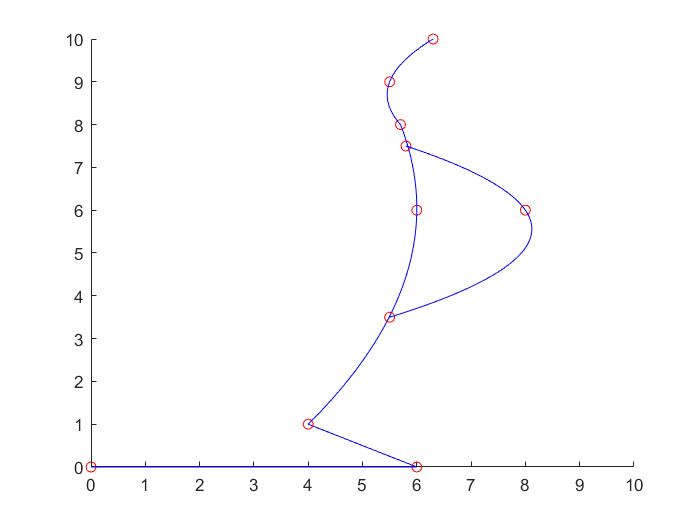

%Ecuación 1
 x1_plot=linspace(A1(1,2),A1(2,2),100);
 y1_plot=X1(2)*x1_plot+X1(1);
 
 %Graficar
 hold on
 plot(A1(:,2),B1,"ro")
 plot(x1_plot,y1_plot,"b")
 
 
 
 %Ecuación 2
 y2_plot=linspace(A2(1,2),A2(3,2),100);
 x2_plot=X2(3)*y2_plot.^2+X2(2)*y2_plot+X2(1);
 
 %Graficar
 plot(B2,A2(:,2),"ro")
 plot(x2_plot,y2_plot,"b")
 
 
 
 %Ecuación 3
 y3_plot=linspace(A3(1,2),A3(3,2),100);
 x3_plot=X3(3)*y3_plot.^2+X3(2)*y3_plot+X3(1);
 
 %Graficar
 plot(B3,A3(:,2),"ro")
 plot(x3_plot,y3_plot,"b")
 
 
 
 %Ecuación 4 (agarradera)
 y4_plot=linspace(A4(1,2),A4(3,2),100);
 x4_plot=X4(3)*y4_plot.^2+X4(2)*y4_plot+X4(1);
 
 %Graficar
 plot(B4,A4(:,2),"ro")
 plot(x4_plot,y4_plot,"b")
 
 
 %Ecuación 5
 x5_plot=linspace(A5(1,2),A5(2,2),100);
 y5_plot=X5(2)*x5_plot+X5(1);
 
 %Graficar
 plot(A5(:,2),B5,"ro")
 plot(x5_plot,y5_plot,"b")
 
 
 %Para fijar los ejes
 axis([0 10 0 10])
 
 hold off

## Sólido de revolución

Utilizamos la función cylinder para formar el sólido de revolución de la siguiente manera: cylinder(radio, número de puntos que queremos que sean generados), donde el radio es el rango de x en cada ecuación. Posteriormente, implementamos la función surf para graficar los sólidos creados.

Para la función surf, obtuvimos la proporción de alturas y las multiplicamos por Z para que en la gráfica cada ecuación/parte de la taza tenga el tamaño adecuado. Además, conforme se agregan más ecuaciones, se le va sumando la altura de la ecuación anterior para que la gráfica nueva aparezca en la parte superior (como colocar una pieza sobre otra).

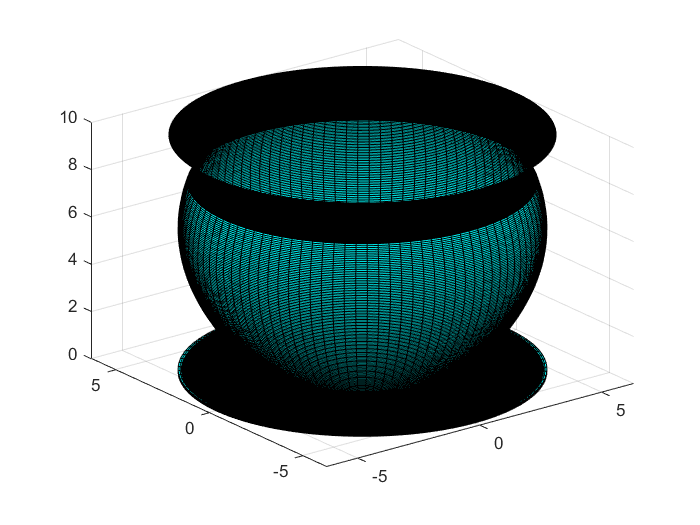

figure(2)
%Ecuación 1
[X, Y, Z] = cylinder(x1_plot,100);
surf(X, Y, Z, 'facecolor', 'c')
hold on

%Ecuación 2
[X, Y, Z] = cylinder(x2_plot,100);
surf(X, Y, 7*Z+1, 'facecolor', 'c')

%Ecuación 3
[X, Y, Z] = cylinder(x3_plot,100);
surf(X, Y, 2*Z+8, 'facecolor', 'c')

%Ecuación 5
[X, Y, Z] = cylinder(x5_plot,100);
surf(X, Y, 0.1*Z, 'facecolor', 'c')

hold off

## Cálculo de volumen completo de la taza

Al realizar las integrales definidas de las ecuaciones obtenidas a través de la interpolación elevadas al cuadrado y posteriormente multiplicar por pi, calculamos el volumen de cada uno de los pedazos de la taza. De esa manera, al sumar los tres resultados conseguimos el volumen completo de la taza. Este resultado incluye el espacio interior del recipiente, es decir, incluye el volumen de líquido que puede contener. Debido a que ese espacio no estará relleno de vidrio, este no es el volumen definitivo que usaremos para cotizar el precio para la taza.

%Ecuación 1
syms x; 
f1 = X1(2)*x + X(1);
vol1 = double(int((f1)^2,x,A1(2,2),A1(1,2))*pi)

vol1 = 39.7935


%Ecuación 2
syms y;
f2 = X2(3)*y.^2 + X2(2)*y + X2(1);

vol2 = double(int((f2)^2,y,A2(1,2),A2(3,2)) * pi)

vol2 = 670.3250


%Ecuación 3
f3 = X3(3)*y.^2+X3(2)*y+X3(1);

vol3 = double(int((f3)^2,y,A3(1,2),A3(3,2)) *pi)

vol3 = 202.0882



voltotal = vol1 + vol2 + vol3

voltotal = 912.2067

## Silueta interior del vidrio

### Interpolaciones

Para conseguir la silueta interior del vidrio, realizamos interpolaciones iguales a las anteriores. La diferencia es que aquí los valores de "x" son 1 unidad menores que los valores del exterior de la taza, de manera que el vidrio tendrá un grosor de 1 unidad. Además, el valor de "y" en los puntos de la base son 1 unidad mayores con el mismo propósito de darle 1 unidad de grosor al vidrio de la base.

%PUNTOS
%Para la taza
vx1 = 5.3;
vx2 = 4.5;
vx3 = 4.7;
vx4 = 5;
vx5 = 3;

vx10 = 0;

vy1 = 10;
vy2 = 9;
vy3 = 8;
vy4 = 6;
vy5 = 1;

vy10 = 1;

%Para la agarradera
vx7 = 5.95;
vx8 = 7;
vx9 = 5.8;

vy7 = 6.5;
vy8 = 6;
vy9 = 4.5;

%INTERPOLACIÓN
%Ecuación 2
vA2 = [1 vy5 vy5^2 ; 1 vy4 vy4^2 ; 1 vy3 vy3^2 ];
vB2 = [vx5;vx4;vx3];

vX2 = inv(vA2)*vB2;


%Ecuación 3
vA3 = [1 vy3 vy3^2; 1 vy2 vy2^2; 1 vy1 vy1^2];
vB3 = [vx3; vx2; vx1];

vX3 = inv(vA3)*vB3;

%Ecuación 4
vA4 = [1 vy9 vy9^2; 1 vy8 vy8^2; 1 vy7 vy7^2]

vA4 =     1.0000    4.5000   20.2500
    1.0000    6.0000   36.0000
    1.0000    6.5000   42.2500


vB4 = [vx9; vx8; vx7]

vB4 =     5.8000
    7.0000
    5.9500



vX4 = inv(vA4)*vB4

vX4 =   -36.9500
   16.0250
   -1.4500




%Ecuación 5
vA5 = [1,vx10;1,vx5];
vB5 = [vy10;vy5];

vX5=inv(vA5)*vB5;


### Gráfica del perfil con silueta interior

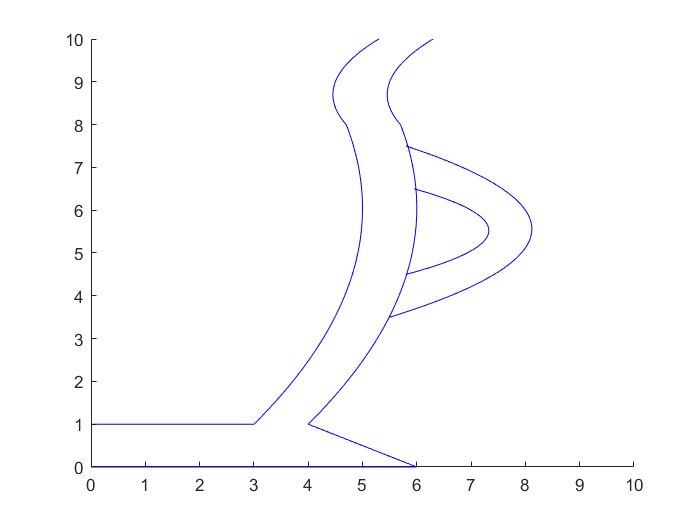

figure(3)
 
%SILUETA INTERIOR
%Ecuación 2
vy2_plot=linspace(vA2(1,2),vA2(3,2),100);
vx2_plot=vX2(3)*vy2_plot.^2+vX2(2)*vy2_plot+vX2(1);
 
%Graficar
hold on
plot(vx2_plot,vy2_plot,"b")


%Ecuación 3
vy3_plot=linspace(vA3(1,2),vA3(3,2),100);
vx3_plot=vX3(3)*vy3_plot.^2+vX3(2)*vy3_plot+vX3(1);

%Graficar
plot(vx3_plot,vy3_plot,"b")


%Ecuación 4 (agarradera)
vy4_plot=linspace(vA4(1,2),vA4(3,2),100);
vx4_plot=vX4(3)*vy4_plot.^2+vX4(2)*vy4_plot+vX4(1);

%Graficar
plot(vx4_plot,vy4_plot,"b")


%Ecuación 5
vx5_plot=linspace(vA5(1,2),vA5(2,2),100);
vy5_plot=vX5(2)*vx5_plot+vX5(1);

%Graficar
plot(vx5_plot,vy5_plot,"b")
 
 
 
%SILUETA EXTERIOR
%Ecuación 1
x1_plot=linspace(A1(1,2),A1(2,2),100);
y1_plot=X1(2)*x1_plot+X1(1);

%Graficar
plot(x1_plot,y1_plot,"b")


%Ecuación 2
y2_plot=linspace(A2(1,2),A2(3,2),100);
x2_plot=X2(3)*y2_plot.^2+X2(2)*y2_plot+X2(1);

%Graficar
plot(x2_plot,y2_plot,"b")


%Ecuación 3
y3_plot=linspace(A3(1,2),A3(3,2),100);
x3_plot=X3(3)*y3_plot.^2+X3(2)*y3_plot+X3(1);

%Graficar
plot(x3_plot,y3_plot,"b")


%Ecuación 4 (agarradera)
y4_plot=linspace(A4(1,2),A4(3,2),100);
x4_plot=X4(3)*y4_plot.^2+X4(2)*y4_plot+X4(1);

%Graficar
plot(x4_plot,y4_plot,"b")


%Ecuación 5
x5_plot=linspace(A5(1,2),A5(2,2),100);
y5_plot=X5(2)*x5_plot+X5(1);

%Graficar
plot(x5_plot,y5_plot,"b")



%Para fijar los ejes
axis([0 10 0 10])

hold off

### Cálculo de volúmen del interior de la taza

Al calcular el volúmen de la silueta interior, estamos calculando el volumen de la taza que será ocupado por la bebida. Esto nos servirá para poder restarle el resultado obtenido al volumen completo calculado anteriormente, de manera que terminaremos únicamente con el volumen de la taza que es ocupado por vidrio.

%Ecuación 2
syms y;
fi2 = vX2(3)*y.^2 + vX2(2)*y + vX2(1);

voli2 = double(int((fi2)^2,y,vA2(1,2),vA2(3,2)) * pi)

voli2 = 450.7801


%Ecuación 3
fi3 = vX3(3)*y.^2 + vX3(2)*y + vX3(1);

voli3 = double(int((fi3)^2,y,vA3(1,2),vA3(3,2)) *pi)

voli3 = 137.1619



volitotal = voli2 + voli3

volitotal = 587.9420

## Volumen de vidrio y cotización

Una vez que tenemos el volumen completo de la taza (voltotal) y el volumen interior que es ocupado por la bebida (volitotal), podemos realizar la resta para finalmente obtener el espacio de la taza que es ocupado por vidrio. Con este dato, podemos determinar la masa del producto al investigar cuál es la densidad del vidrio. De acuerdo a nuestras referencias presentadas en el reporte, la densidad del vidrio es de 2.58 g/cm3, 1kg de vidrio reciclado cuesta $1.20 y el dispositivo para calentar la bebida cuesta $150.00. En base a estos datos, implementamos la fórmula de densidad para conseguir la masa de nuestra taza y posteriormente poder cotizar un precio del producto final.

volumen = voltotal - volitotal

volumen = 324.2647


%Datos que investigamos
densidad = 2.58

densidad = 2.5800

preciobase = 150

preciobase = 150


%Cálculo del precio final
masa = (densidad * volumen)/1000

masa = 0.8366

preciovidrio = 1.2*masa

preciovidrio = 1.0039


preciofinal = preciovidrio + preciobase

preciofinal = 151.0039